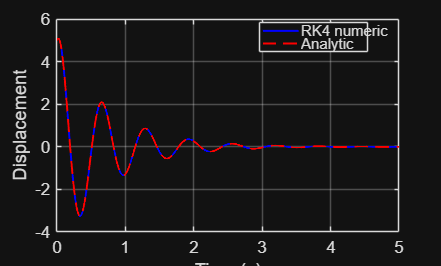

wn = 10;
zeta = 0.14;

x0 = 5;
v0 = 10;
X0 = [x0; v0];

dt = 0.001;
T = 5;
t = 0:dt:T;

% ODE
f = @(t,X) [ X(2);
              -wn^2*X(1) - 2*zeta*wn*X(2)];

% RK4 single step
function Xn = rk4step(fun, t, X, h)
    k1 = fun(t, X);
    k2 = fun(t+h/2, X+h/2 * k1);
    k3 = fun(t+h/2, X+h/2 * k2);
    k4 = fun(t+h, X+h * k3);
    Xn = X + h/6 * (k1 + 2*k2 + 2*k3 + k4);
end

% Integrate with RK4
X = zeros(2, numel(t));
X(:,1) = X0;
for i = 1:numel(t)-1
    X(:,i+1) = rk4step(f, t(i), X(:,i), dt);
end
x_num = X(1,:);

% Analytic solution
if zeta < 1
    % Underdamped
    wd = wn*sqrt(1 - zeta^2);
    A = x0;
    B = (zeta*wn*x0 + v0)/wd;
    x_analytic = exp(-zeta*wn*t) .* ( A.*cos(wd*t) + B.*sin(wd*t) );
elseif abs(zeta - 1) < 1e-12
    % Critically damped (zeta == 1)
    % x(t) = (A + B*t) * exp(-wn*t)
    A = x0;
    B = v0 + wn*x0;
    x_analytic = (A + B.*t) .* exp(-wn*t);
else
    % Overdamped (zeta > 1)
    r1 = -wn*(zeta - sqrt(zeta^2 - 1));
    r2 = -wn*(zeta + sqrt(zeta^2 - 1));
    C2 = (v0 - r1*x0) / (r2 - r1);
    C1 = x0 - C2;
    x_analytic = C1.*exp(r1.*t) + C2.*exp(r2.*t);
end

% Plot both
figure;
plot(t, x_num, 'b-', 'LineWidth', 1.2); hold on;
plot(t, x_analytic, 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Displacement');
legend('RK4 numeric','Analytic','Location','best');
grid on; hold off;